clc; close all; clear;


## Load TADPOLE diode signal

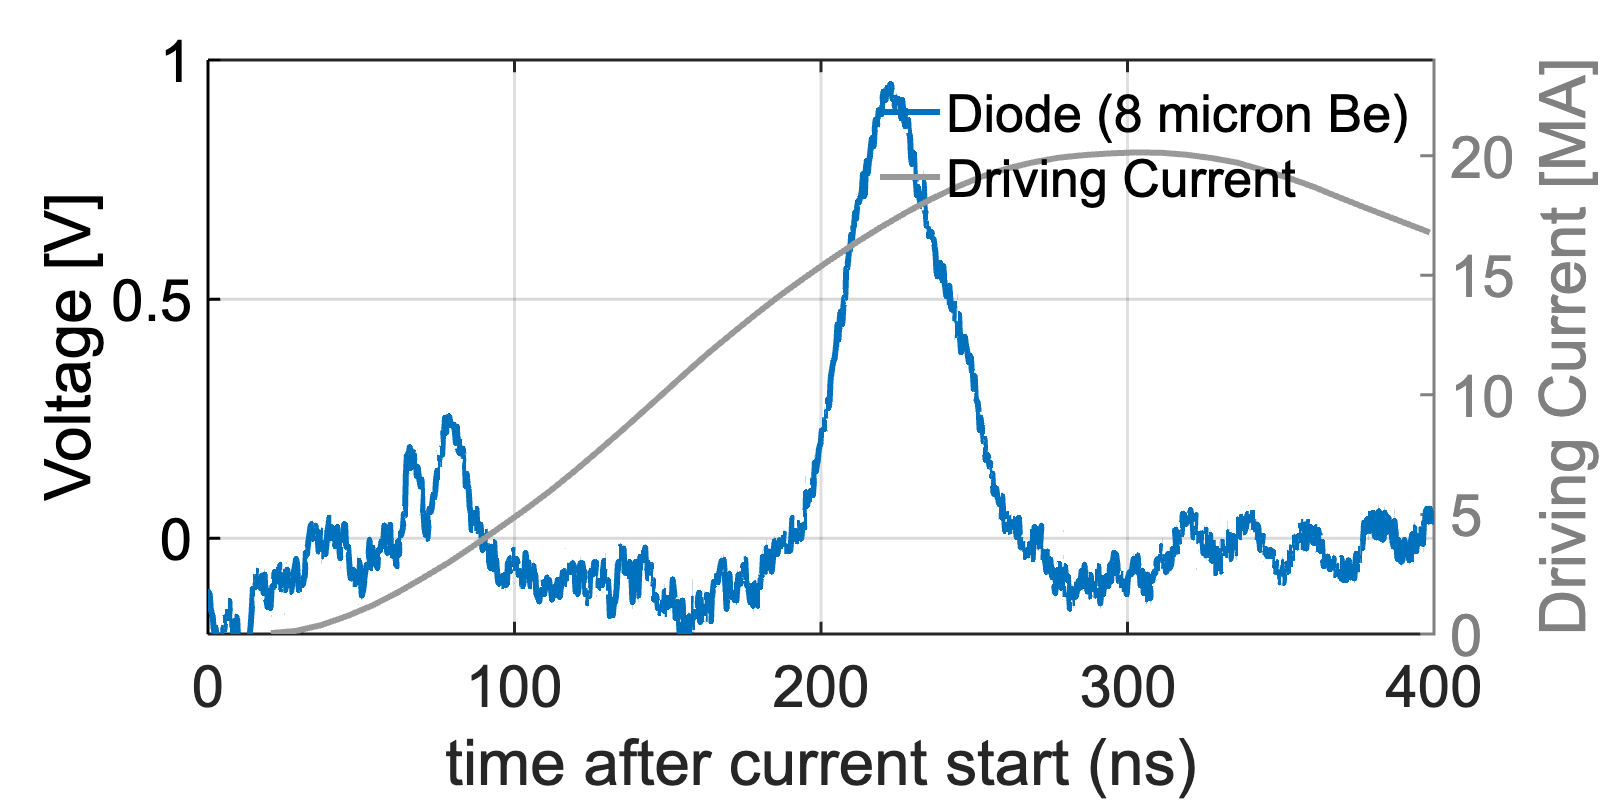

inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\Vacuum FOA\Tadpoles\');
fname = 'sidtada01';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
I = data(:,2);

I = I - mean(I(1:50));

figure
plot(t,I,linewidth=3,DisplayName = 'Diode (8 micron Be)'); hold on;


xlabel('time after current start (ns)'); 
ylabel('Voltage [V]'); 
xlim([0,400]); ylim([-0.2,1])
 grid on;
yyaxis right
data = dlmread("z3697_bcave.csv");
plot(data(:,1)-2800,data(:,2),'LineWidth',3,'DisplayName','Driving Current','Color',[0.6,0.6,0.6]);
ylabel('Driving Current [MA]'); ylim([0,24]);
ax = gca;
ax.YAxis(2).Color = [1,1,1]*0.5;
formatPlots(800,2);

# Show LOS170 Diode signal form MARZ2

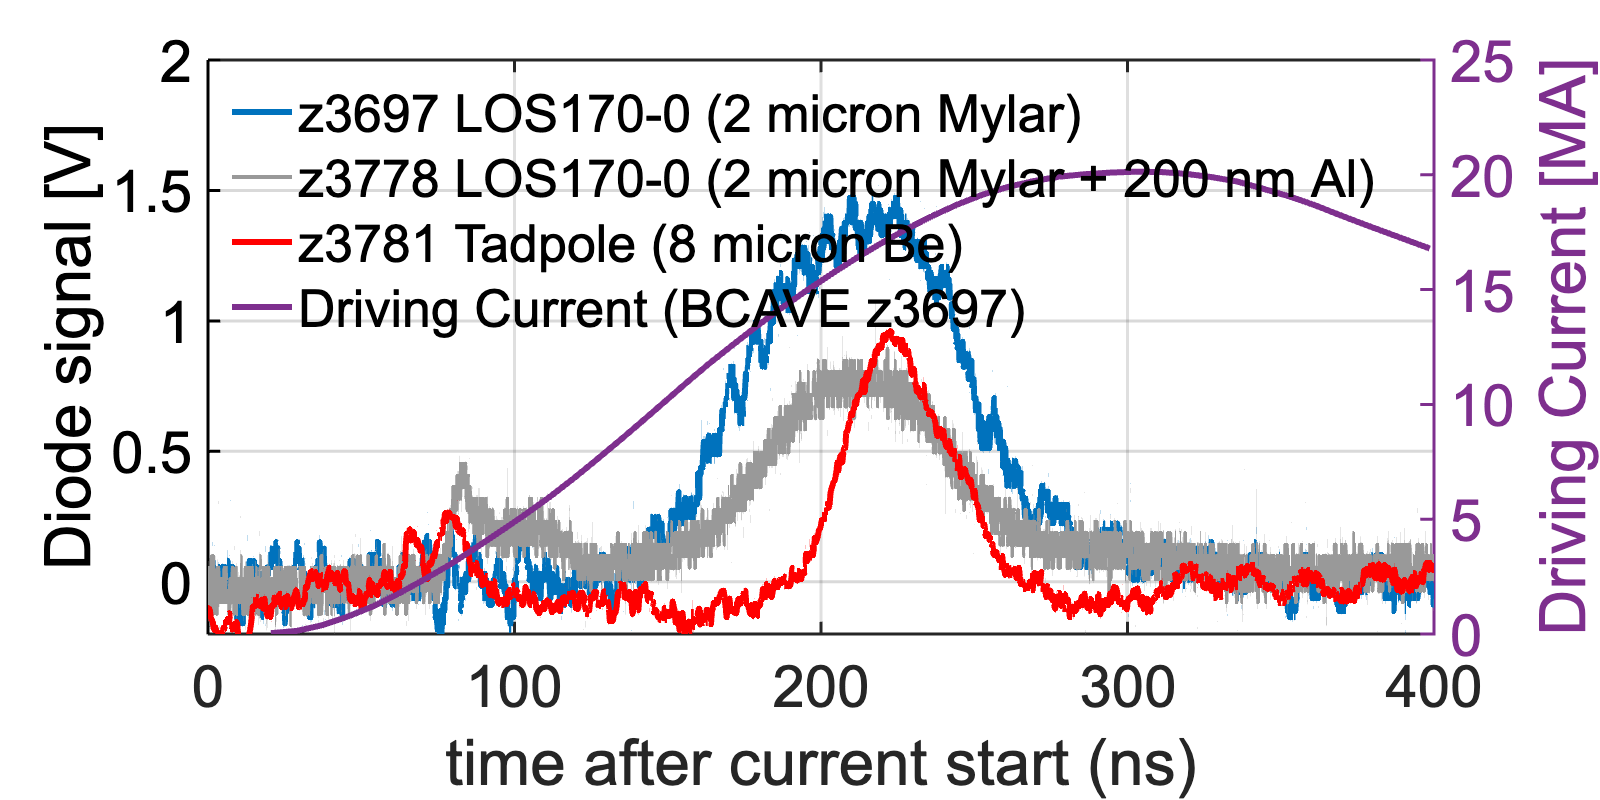



% MARZ 1 LOS-170 Diode
inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ1_z3697\Waveforms\shot3697_all_waveforms_ASCII\');
fname = 'sid17axx001';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
I = data(:,2);

figure
str = sprintf('z3697 LOS170-0 (2 micron Mylar)');
plot(t,I,linewidth=3, DisplayName = str); hold on;


% MARZ 2 LOS-170 Diode
inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ2_z3778\LOS170 Diodes\');
fname = 'sid17axx002';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
I = data(:,2);

hold on;
str = sprintf('z3778 LOS170-0 (2 micron Mylar + 200 nm Al)');
plot(t,I,linewidth=2, DisplayName = str,color=[0.6,0.6,0.6]); hold on;

% MARZ3 tadpole

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\Vacuum FOA\Tadpoles\');
fname = 'sidtada01';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
I = data(:,2);

plot(t,I,linewidth=3,DisplayName = 'z3781 Tadpole (8 micron Be)',color='r'); hold on;


xlabel('time after current start (ns)'); 
ylabel('Diode signal [V]'); 
xlim([0,400]); ylim([-0.2,2])
legend();
formatPlots(900,2); grid on;
% current 

data = dlmread("z3697_bcave.csv");
yyaxis right
plot(data(:,1)-2800,data(:,2),'LineWidth',3,'DisplayName','Driving Current (BCAVE z3697)');
ylabel('Driving Current [MA]')
legend('NumColumns',1,'location','northwest')
formatPlots(800,2); xlim([0,400])

## Converting to Power Units from Voltage

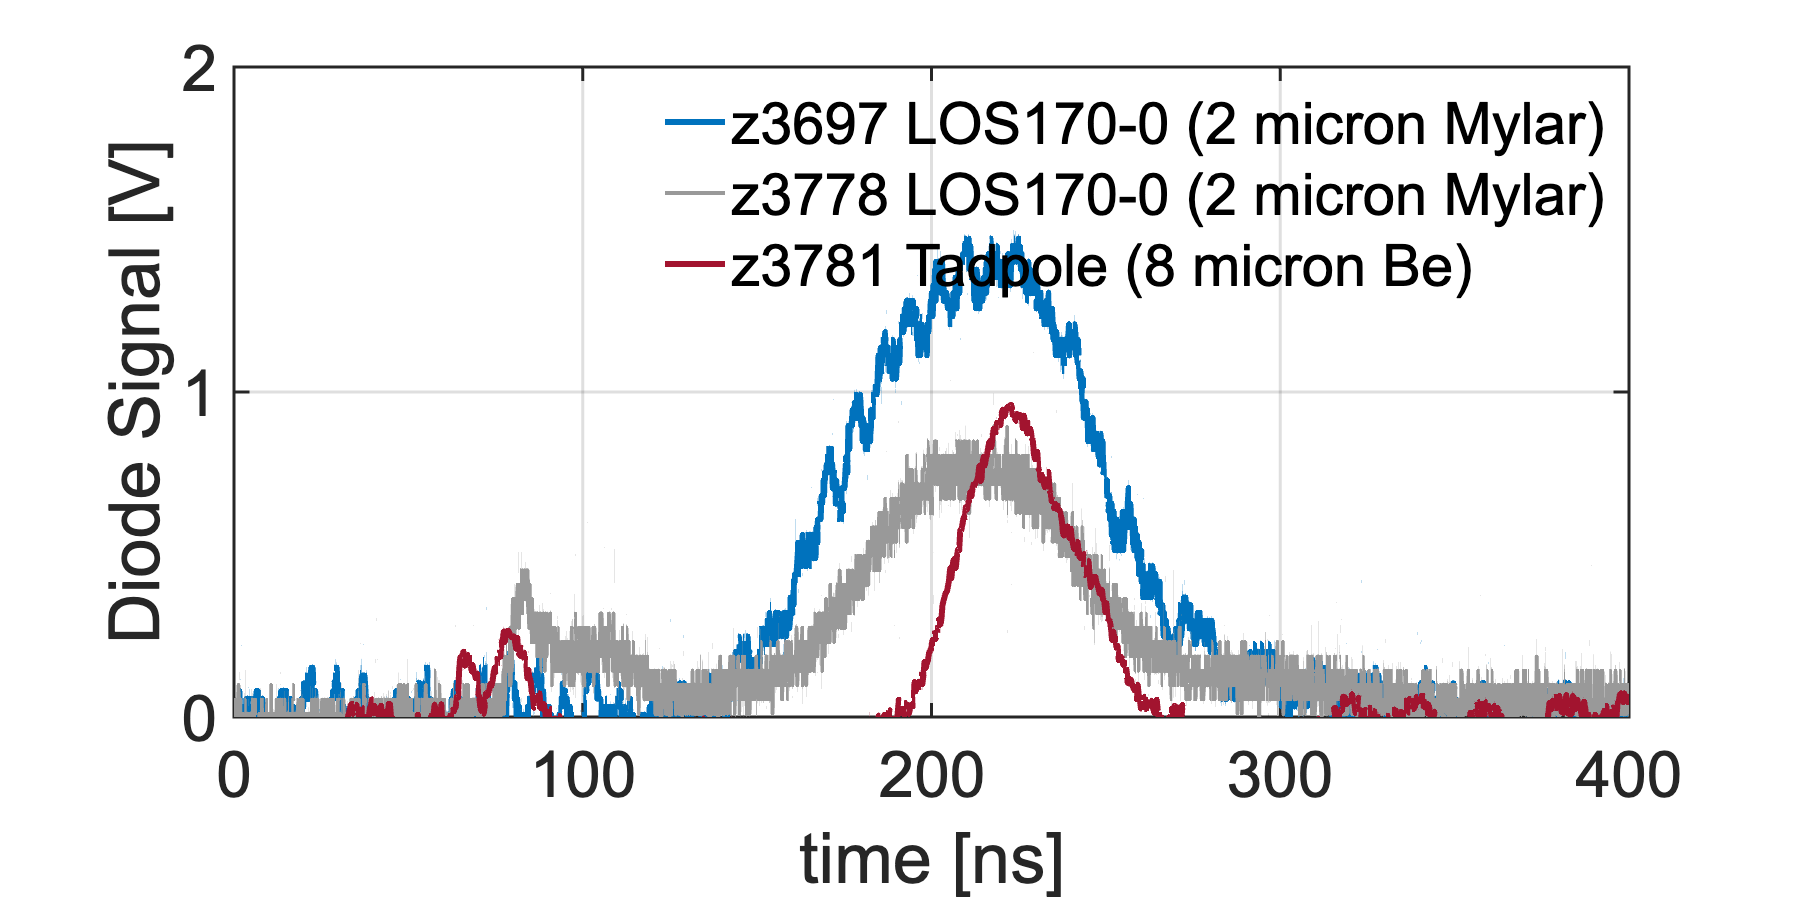



% Convert to Power Units

R = 50; % Ohm
res = 0.276; % A/W

% MARZ 1 LOS-170 Diode
inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ1_z3697\Waveforms\shot3697_all_waveforms_ASCII\');
fname = 'sid17axx001';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
V = data(:,2);
P = V / (R * res); % W, X-Ray Measured Power

figure
str = sprintf('z3697 LOS170-0 (2 micron Mylar)');
plot(t,V,linewidth=3, DisplayName = str); hold on;


% MARZ 2 LOS-170 Diode
inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ2_z3778\LOS170 Diodes\');
fname = 'sid17axx002';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
V = data(:,2);
P = V / (R * res); % W

hold on;
str = sprintf('z3778 LOS170-0 (2 micron Mylar)');
plot(t,V,linewidth=2, DisplayName = str,color=[0.6,0.6,0.6]); hold on;

% MARZ3 tadpole

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\Vacuum FOA\Tadpoles\');
fname = 'sidtada01';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
V = data(:,2);
P = V / (R * res); % W

plot(t,V,linewidth=3,DisplayName = 'z3781 Tadpole (8 micron Be)',color='#A2142F'); hold on;


xlabel('time [ns]'); 
ylabel('Diode Signal [V]'); 
xlim([0,400]); 
ylim([0,2])
yticks([0,1,2])

formatPlots(900,2); grid on;











% % current 
% 
% data = dlmread("z3697_bcave.csv");
% yyaxis right
% plot(data(:,1)-2800,data(:,2),'LineWidth',3,'DisplayName','Driving Current (BCAVE z3697)');
% ylabel('Driving Current [MA]')
% legend('NumColumns',1,'location','northwest')
% formatPlots(800,2); xlim([0,400])

% Convert to Power Units

R = 50; % Ohm
res = 0.276; % A/W

% MARZ 1 LOS-170 Diode
inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ1_z3697\Waveforms\shot3697_all_waveforms_ASCII\');
fname = 'sid17axx001';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
V = data(:,2);
P = V / (R * res); % W

figure
str = sprintf('z3697 LOS170-0 (2 micron Mylar)');
plot(t,V,linewidth=3, DisplayName = str); hold on;


% MARZ 2 LOS-170 Diode
inDir = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ2_z3778\LOS170 Diodes\');
fname = 'sid17axx002';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
V = data(:,2);
P = V / (R * res); % W

hold on;
str = sprintf('z3778 LOS170-0 (2 micron Mylar)');
plot(t,V,linewidth=2, DisplayName = str,color=[0.6,0.6,0.6]); hold on;

% MARZ3 tadpole

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\Vacuum FOA\Tadpoles\');
fname = 'sidtada01';

data = dlmread([inDir,fname]);

t = data(:,1)*1e9-2800;
V = data(:,2);
P = V / (R * res); % W

plot(t,V,linewidth=3,DisplayName = 'z3781 Tadpole (8 micron Be)',color='#A2142F'); hold on;


xlabel('time [ns]'); 
ylabel('Diode Signal [V]'); 
xlim([0,400]); 
ylim([0,2])
yticks([0,1,2])

formatPlots(900,2); grid on;

% legend(fontsize=20,box='on');